# V768 - Measuring Vision with Psychophysics

## Lab 8 - Motion Adaptation

In this lab, we will use a technique called top-up adaptation to measure the perceptual effects of motion adaptation.

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Build a simple experiment using PsychoPy.

- Explain the impact of motion adaptation on the perception of motion direction in a motion direction discrimination task.

### Questions

- Explain what top-up adaptation is.

- Include and write a caption for the LAST figure in Part A, Step 3 (Analyze the data).

- Include and write a caption for the LAST figure in Part B, Step 3 (Analyze the data).

- Compare the results from both experiments. What is similar? What is different? If there are differences, explain what caused them.

## Part A. Simple Motion Coherence Experiment

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "motion-simple-example", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 140 trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("motion-simple-example", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id+"*.csv";
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
demo_motion-simple-example_2025-03-04_22h13.50.730.csv


**Confirm that your data file is listed above.** There should be one file.

#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
expt_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    this_data(1,:) = [];  % remove row on expt instructions
    expt_data = [expt_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
expt_data(:,remove) = [];

% display data table size
n_trials = size(expt_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 140


### Step 3. Analyze your data

For this experiment, the stimulus was a field of dots. Both direction of motion and motion coherence varied. The coherence defines the proportion of dots that move in the direction of motion. The direction of motion was either to the right (0 degrees) or to the left (180 degrees), and the task was to report whether the motion was rightward or leftward.

For each trial, PsychoPy saved the motion direction, the motion coherence, and the participant's response. The responses were stored as 'left' or 'right'.

% stash the stimulus location and response data
motion_coherence = expt_data.coherence;
motion_direction = expt_data.direction;
resp_key = expt_data.key_resp_keys;

% convert stimulus motion direction to 1 for right and -1 for left
motion_direction(motion_direction == 180) = -1;
motion_direction(motion_direction == 0) = 1;

% calculate signed motion coherence
signed_motion_coherence = motion_coherence .* motion_direction;

% convert the response key to 1 for right and -1 for left
% (to match stimulus direction)
resp_direction = double(strcmp(resp_key,'right'));
resp_direction(resp_direction==0) = -1;

#### Determine whether responses were correct or incorrect

For a response to be correct, the stimulus motion and response directions must match.

% determine whether responses were correct or incorrect
resp_correct = motion_direction == resp_direction;

% determine whether participant chose right
chose_right = resp_direction == 1;

% display overall performance
fprintf('overall percentage correct = %.2f%%\n', mean(resp_correct)*100);

overall percentage correct = 83.57%


#### Determine performance per condition

We need to now separate responses by stimulus condition to visualize performance in a psychometric curve. To accomplish that, we can separate by the signed motion coherence values that we calculated above. (Positive values indicate rightward motion, and negative values indicate leftward motion.)

% average across responses per contrast level
analysis_table = table(chose_right, signed_motion_coherence,...
    'VariableNames',["response", "coherence"]);
expt_results = grpstats(analysis_table, "coherence");
expt_results = renamevars(expt_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prob_right"]);
expt_results.Properties.RowNames = {};

% stash stimulus levels & counts
coherence_levels = unique(expt_results.coherence);
n_coherence = length(coherence_levels);

% display results
disp(expt_results)

    coherence    n_trials    prob_right
    _________    ________    __________

        -1          10             0   
      -0.5          10             0   
      -0.4          10             0   
      -0.3          10             0   
      -0.2          10           0.1   
      -0.1          10           0.2   
         0          20          0.45   
       0.1          10           0.7   
       0.2          10           0.9   
       0.3          10           0.9   
       0.4          10             1   
       0.5          10             1   
         1          10             1   



#### Plot performance per condition

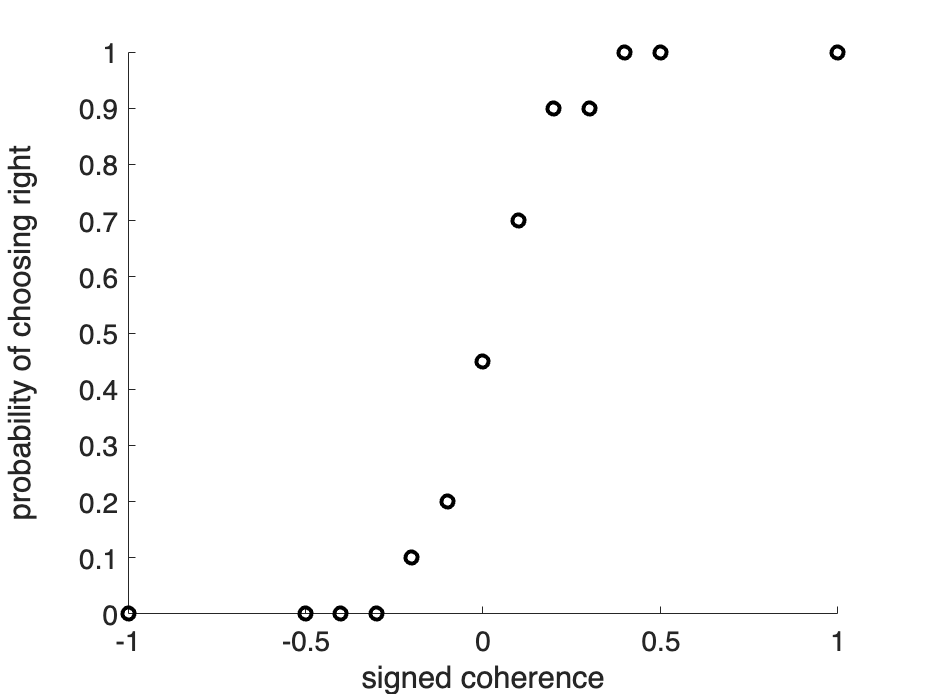

figure; hold on
scatter(expt_results.coherence,expt_results.prob_right,'k','LineWidth',2)
xlabel("signed coherence")
ylabel(["probability of choosing right",""])
set(gca,'FontSize',14);

drawnow

#### **Fit data.**

% choose initial parameter values
init_params = [0, 5, .1, .1];

% fit psychometric curve to data
[expt_params, neg_log_likelihood] = fmincon(@(params) ...
    negLogLikelihood(params,...
    (expt_results.coherence),...
    expt_results.prob_right.*expt_results.n_trials,...
    expt_results.n_trials), init_params,...
    [],[],[],[],[0,0,0,0],[180,100,.5,.5]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


discrim_param_table = array2table(expt_params.', ...
    'RowNames',["mu","sigma","gamma","lambda"], 'VariableNames',["fit"]);
disp(discrim_param_table)

                 fit    
              __________

    mu          0.025478
    sigma        0.15771
    gamma      2.993e-09
    lambda    8.8778e-09



#### Plot fit with data.

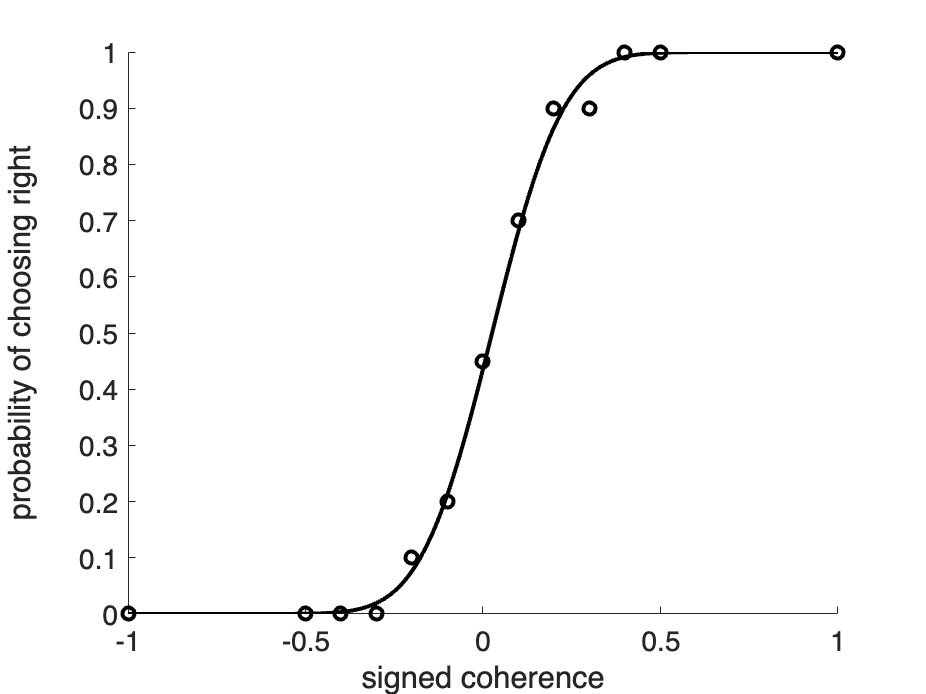

figure; hold on;
xx = -1:.01:1;
yy = psyfxn(expt_params,xx);
scatter(expt_results.coherence,expt_results.prob_right,'k','LineWidth',2)
plot((xx),yy,'k-','LineWidth',2)
xlabel("signed coherence")
ylabel(["probability of choosing right",""])
set(gca,'FontSize',14);

drawnow

#### Calculate and plot both PSE and JND

% calculate PSE
pse = (ipsyfxn(expt_params,.5))

pse = 0.0255

% calculate JND
jnd = expt_params(:,2)/sqrt(2) % this is in log direction units

jnd = 0.1115

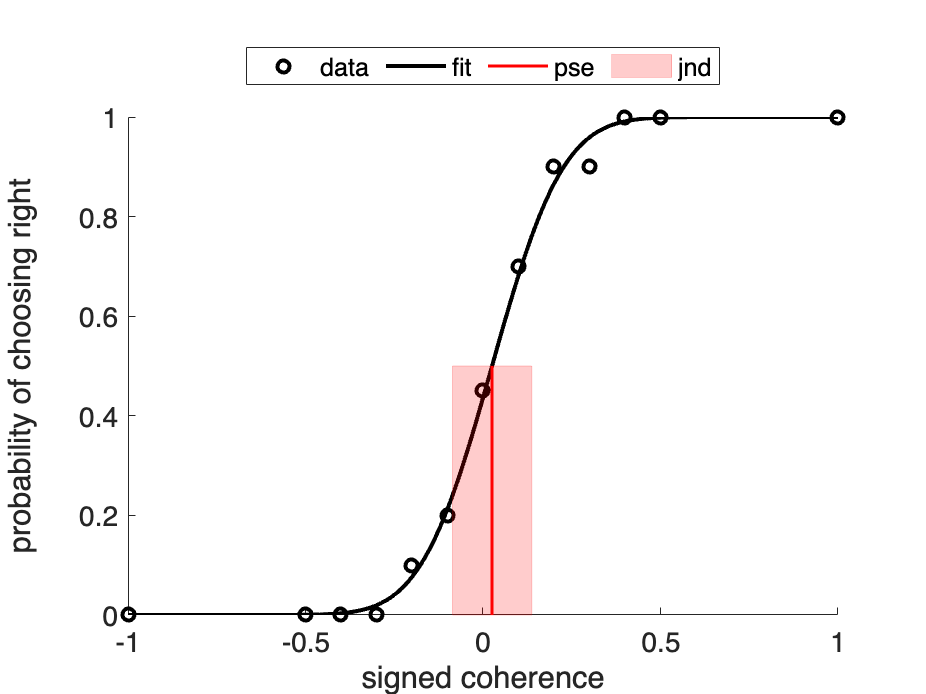

% plot the PSE +/- JND along with the data and fitted curve
figure; hold on;
   
scatter(expt_results.coherence,expt_results.prob_right,'k','LineWidth',2)
plot((xx),yy,'k-','LineWidth',2)
plot(pse*[1,1],[0,.5],'r-','LineWidth',1.5)
jnd_x = [pse-jnd,pse+jnd,pse+jnd,pse-jnd,pse-jnd];
jnd_y = [0,0,.5,.5,0];
patch(jnd_x,jnd_y,'r','FaceAlpha',.2,'EdgeColor','r','EdgeAlpha',.2);

set(gca,'FontSize',14);
xlabel("signed coherence")
ylabel(["probability of choosing right",""])
legend(["data", "fit", "pse", "jnd"],'Location','northoutside','NumColumns',4)

**What do you see?** What do you expect to happen to this curve if you perform the experiment while being adapted to motion to the right?  What about to the left?

## Part B. Motion Adaptation Experiment

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "motion-adaptation", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 140 trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("motion-adaptation", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id+"*.csv";
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
demo_motion-adaptation_2025-03-05_19h44.16.495.csv


**Confirm that your data file is listed above.** There should be one file.

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
adapt_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    this_data(1,:) = [];  % remove row on expt instructions
    adapt_data = [adapt_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
adapt_data(:,remove) = [];

% remove first row
adapt_data(1,:) = [];

% display data table size
n_trials = size(adapt_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 140


### Step 3. Analyze your data

For this experiment, the stimulus was a field of dots. Both direction of motion and motion coherence varied. The coherence defines the proportion of dots that move in the direction of motion. The direction of motion was either to the right (0 degrees) or to the left (180 degrees), and the task was to report whether the motion was rightward or leftward.

For each trial, PsychoPy saved the motion direction, the motion coherence, and the participant's response. The responses were stored as 'left' or 'right'.

% stash the stimulus location and response data
motion_coherence = adapt_data.coherence;
motion_direction = adapt_data.direction;
resp_key = adapt_data.key_resp_keys;

% convertion stimulus motion direction to 1 for right and -1 for left
motion_direction(motion_direction == 180) = -1;
motion_direction(motion_direction == 0) = 1;

% create signed motion coherence
signed_motion_coherence = motion_coherence.*motion_direction;

% convert the response key to 1 for right and -1 for left
% (to match stimulus location)
resp_direction = double(strcmp(resp_key,'right'));
resp_direction(resp_direction==0) = -1;

#### Determine whether responses were correct or incorrect

For a response to be correct, the motion direction must match the response direction.

% determine whether responses were correct or incorrect
resp_correct = motion_direction == resp_direction;

chose_right = resp_direction == 1;

% display overall performance
fprintf('overall percentage correct = %.2f%%\n', mean(resp_correct)*100);

overall percentage correct = 80.71%


#### Determine performance per condition

We need to now separate by coherence and direction to visualize performance in a psychometric curve.

% average across responses per contrast level
analysis_table = table(chose_right, signed_motion_coherence,...
    'VariableNames',["response", "coherence"]);
adapt_results = grpstats(analysis_table, "coherence");
adapt_results = renamevars(adapt_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prob_right"]);
adapt_results.Properties.RowNames = {};

% stash stimulus levels & counts
coherence_levels = unique(adapt_results.coherence);
n_coherence = length(coherence_levels);

% display results
disp(adapt_results)

    coherence    n_trials    prob_right
    _________    ________    __________

        -1          10             0   
      -0.5          10             0   
      -0.4          10             0   
      -0.3          10             0   
      -0.2          10           0.1   
      -0.1          10           0.2   
         0          20          0.05   
       0.1          10           0.6   
       0.2          10           0.5   
       0.3          10           0.8   
       0.4          10             1   
       0.5          10           0.8   
         1          10             1   



#### Plot performance per condition

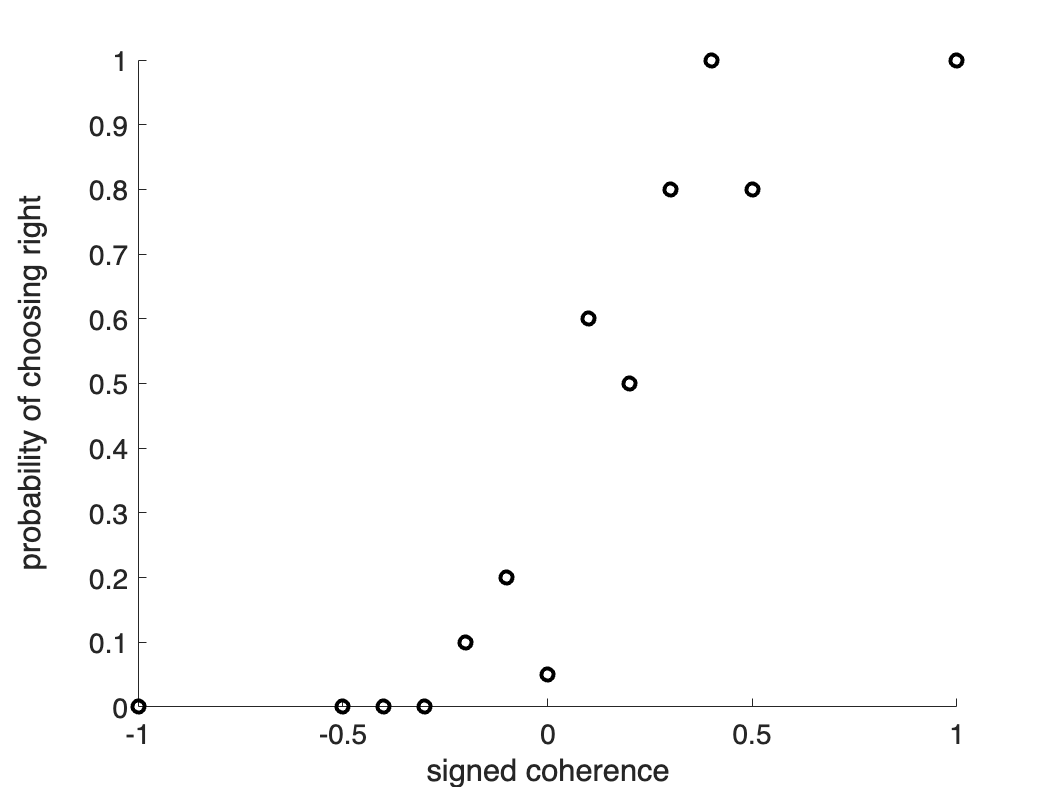

figure; hold on
scatter(adapt_results.coherence,adapt_results.prob_right,'k','LineWidth',2)
xlabel("signed coherence")
ylabel(["probability of choosing right",""])
set(gca,'FontSize',14);

drawnow

#### **Fit data**

% choose initial parameter values
init_params = [0, 5, .1, .1];

% fit psychometric curve to data
[adapt_params, neg_log_likelihood] = fmincon(@(params) ...
    negLogLikelihood(params,...
    (adapt_results.coherence),...
    adapt_results.prob_right.*adapt_results.n_trials,...
    adapt_results.n_trials), init_params,...
    [],[],[],[],[0,0,0,0],[180,100,.1,.1]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


adapt_param_table = array2table(adapt_params.', ...
    'RowNames',["mu","sigma","gamma","lambda"], 'VariableNames',["fit"]);
disp(adapt_param_table)

                 fit    
              __________

    mu           0.16752
    sigma        0.21965
    gamma     3.9295e-09
    lambda    7.7672e-08



#### Plot fit with data

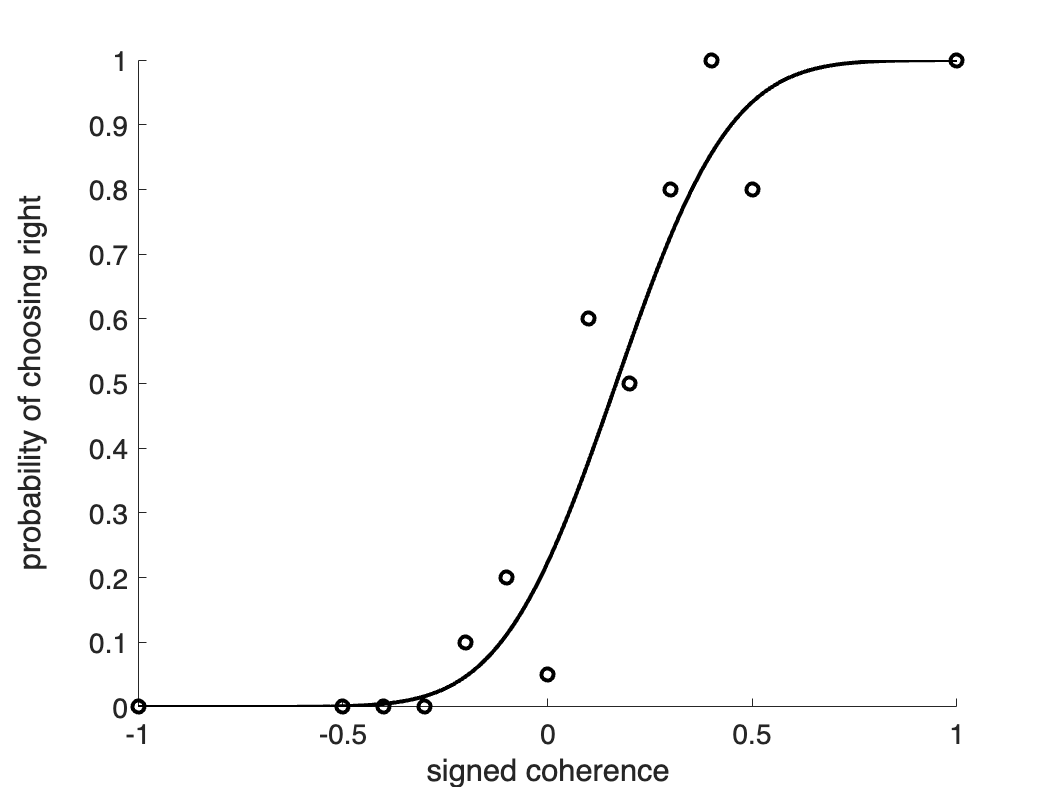

figure; hold on;
xx = -1:.01:1;
yy = psyfxn(adapt_params,xx);
scatter(adapt_results.coherence,adapt_results.prob_right,'k','LineWidth',2)
plot((xx),yy,'k-','LineWidth',2)
xlabel("signed coherence")
ylabel(["probability of choosing right",""])
set(gca,'FontSize',14);

drawnow

#### Calculate and plot both PSE and JND

% calculate PSE
pse = (ipsyfxn(adapt_params,.5))

pse = 0.1675

% calculate JND
jnd = adapt_params(:,2)/sqrt(2) % this is in log direction units

jnd = 0.1553

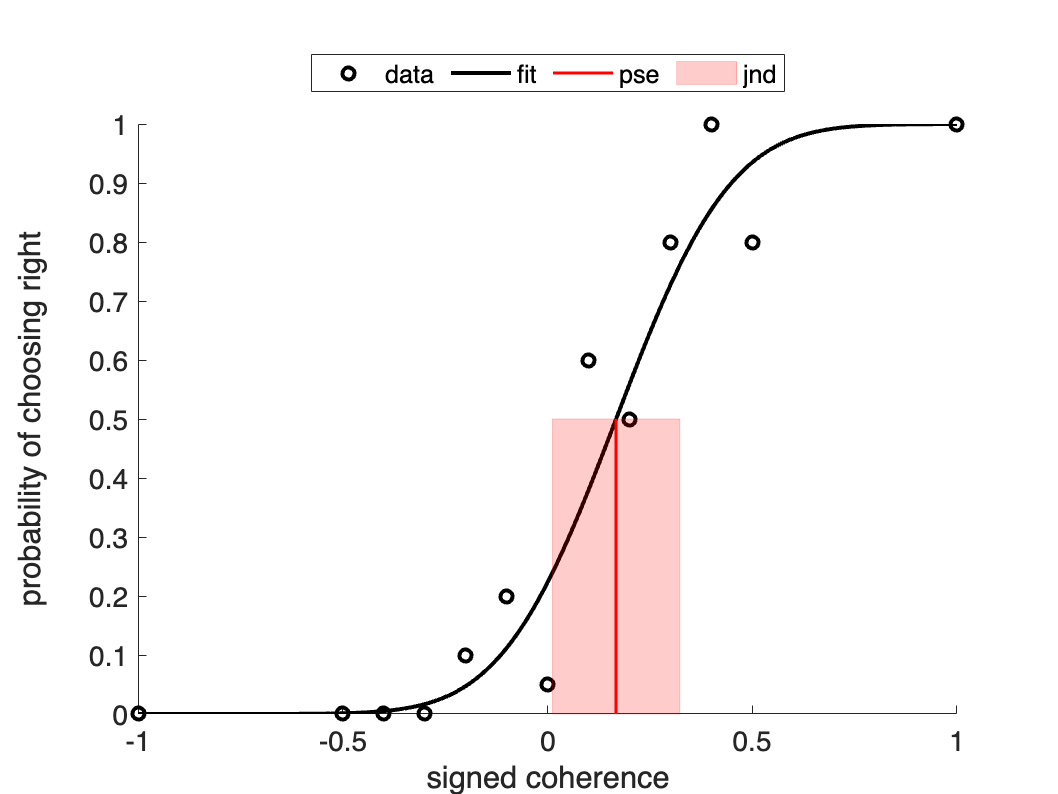

% plot the PSE +/- JND along with the data and fitted curve
figure; hold on;
   
scatter(adapt_results.coherence,adapt_results.prob_right,'k','LineWidth',2)
plot((xx),yy,'k-','LineWidth',2)
plot(pse*[1,1],[0,.5],'r-','LineWidth',1.5)
jnd_x = [pse-jnd,pse+jnd,pse+jnd,pse-jnd,pse-jnd];
jnd_y = [0,0,.5,.5,0];
patch(jnd_x,jnd_y,'r','FaceAlpha',.2,'EdgeColor','r','EdgeAlpha',.2);

set(gca,'FontSize',14);
xlabel("signed coherence")
ylabel(["probability of choosing right",""])
legend(["data", "fit", "pse", "jnd"],'Location','northoutside','NumColumns',4)